load lawdata.mat

gpa

gpa =     3.3900
    3.3000
    2.8100
    3.0300
    3.4400
    3.0700
    3.0000
    3.4300
    3.3600
    3.1300


lsat

lsat =    576
   635
   558
   578
   666
   580
   555
   661
   651
   605


A = [ones(15, 1) gpa];
y = lsat;

A_star = A' * A;
y_star = A' * y;

c = A_star \ y_star

c =   187.8996
  133.2509


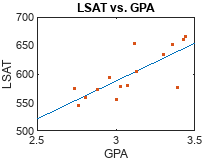


x_vals = linspace(2.5, 3.5, 10000);
y_vals = c(1, 1) + x_vals * c(2, 1);

figure;
plot(x_vals, y_vals, "-", "DisplayName", "Linear Best Fit")
hold on
plot(gpa, lsat, ".")
xlabel("GPA")
ylabel("LSAT")
title("LSAT vs. GPA")


A = [ones(15, 1) gpa gpa .^ 2];
y = lsat;

A_star = A' * A;
y_star = A' * y;

c = A_star \ y_star

c =   517.2826
  -80.2953
   34.4124


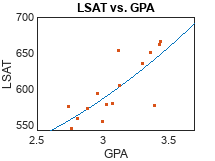


x_vals = linspace(2.6, 3.7, 10000);
y_vals = polyval(flip(c), x_vals);

figure;
plot(x_vals, y_vals, "-")
hold on
plot(gpa, lsat, ".")
xlabel("GPA")
ylabel("LSAT")
title("LSAT vs. GPA")